# FIR Filtering & Voice recognition

#### FIR ( Finite Impulse Response ) is a process where an input signal x(n) is passed through a filter h(n) , and resulting in a new output y(n).

The process for computing this in the discrete - time domain is:

y(n) = h(n) * x(n)  ... Convolution

close all

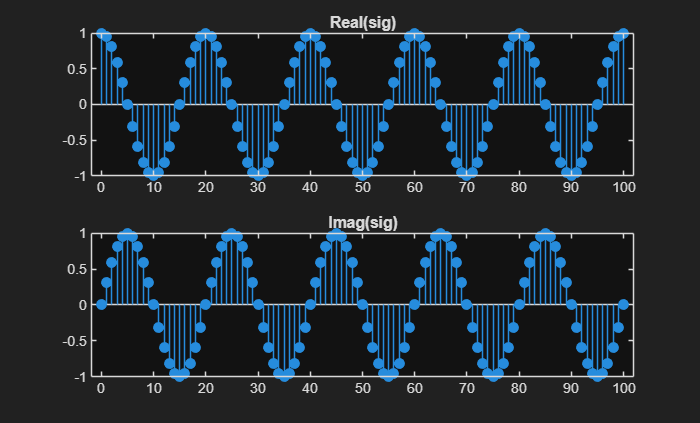

% Lets first initialize a signal in MATLAB:

% No. of samples (n) set to 100 :
n = (0:100) ;

% The signal is e^(j*pi*n):
sig = exp(0.1*j*pi*n) ;

% Plotting the Real and Imaginary parts of the signal:
figure
set(gcf,'Visible','On')
subplot(2,1,1)
stem(n,real(sig),'filled')
title('Real(sig)')
subplot(2,1,2)
stem(n,imag(sig),'filled')
title('Imag(sig)')

Because: e^(jθ) = cos(θ) + jsin(θ)   ... Euler's Formula

#### Real signal: 

cos( 0.1 * pi * n )

#### Imaginary signal: 

j * sin( 0.1 * pi * n )

... The period is n = 20 samples, for the full 2*pi effect.

## Voice Recording:

Firstly, change your directory to " Toolbox " folder.

Then, you need to run " >> startELEC3305 " on your terminal first.

Then, press any button on the command prompt to start audio recording 10s.

% you should use the code below to record audio
recTime = 6.0 ; % seconds
devId = 3 ; % microphone, have to set the right device ID
fs = 48000 ; % I like to use 48 kHz
bufSiz = 2048 ;
userStart = true ; % Haveto press return to start recording
recSig = RecordAudio(recTime, devId, fs, bufSiz, userStart) ;

Press a key to start recording


% Save recording to a file on computer
% as a wav file
audiowrite('sentence.wav', recSig, fs )
% as a mp4 file
audiowrite('sentence.mp4', recSig, fs)

% a default recorded sentence can be loaded
% read in sentence.wav
% [recSig, fs] = audioread('sentence.wav') ;

Now, lets plot the signal:

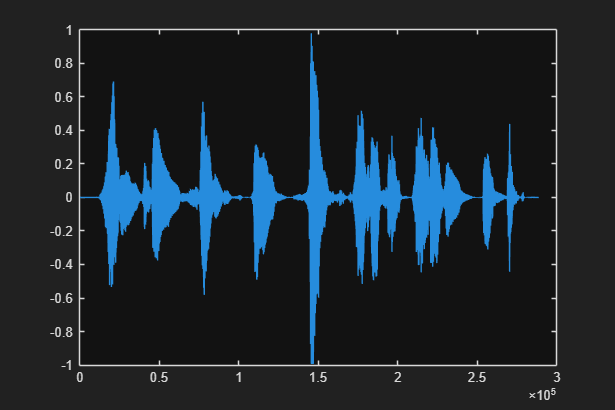

% Plot signal
figure ;
plot(recSig) % x-axis is the sample number
set(gcf,'Visible','On')

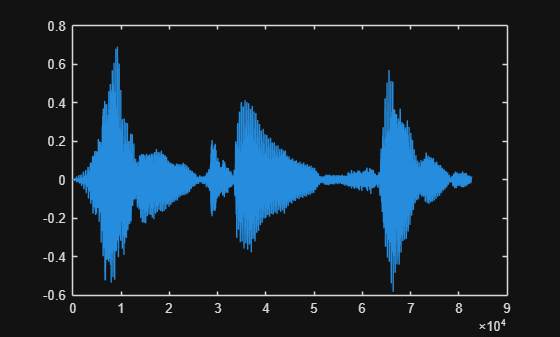

% if the signal extends to =1 or -1 then it has clipped and
% you need to record it again

% window the signal in the time domain
% choose your own indices for windowing
recSig2 = recSig(11854:94530) ;
% plot the windowed signal
figure ;
plot(recSig2)

% play signal
soundsc(recSig2,48000) ;

## FIR Filtering

Consider the acoustic impulse response of a church. It could be measured using a log sine sweep or in the olden days it could be measured with a blank gun shot or the pop of a balloon.

Run the code below.

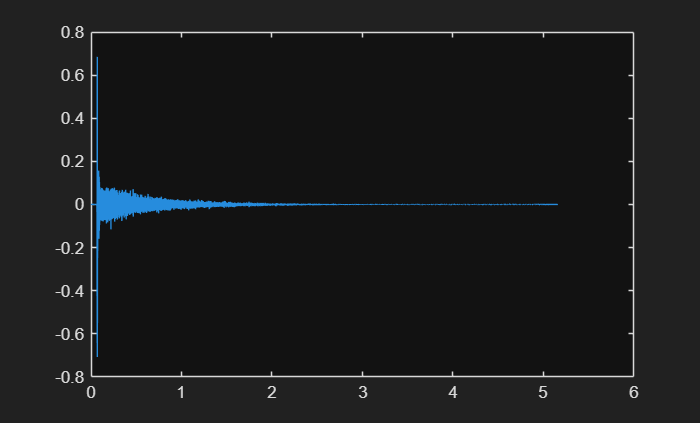

[churchIR, fsIR] = audioread('ChurchImpulseResponse-16-44p1-mono-5secs.wav');
soundsc(churchIR, fsIR)
fh = figure; set(gcf,'Visible','On')
tIR = (0:length(churchIR)-1).'/fsIR ;
plot(tIR,churchIR)

Sounds like a gunshot.

Let's now filter our recorded sentence with the church impulse response.

sigInChurch = filter(resample(churchIR,fs,fsIR),1,recSig) ;
% sigInChurch = conv(resample(churchIR,fs,fsIR),recSig) ;
playObj = audioplayer(sigInChurch,fs) ;
playblocking(playObj) ;
playObj = audioplayer(recSig,fs) ;
playblocking(playObj) ;

`filter(b,a,x)` implements the LTI difference equation whose transfer function is B(z)/A(z).

It processes the input sample-by-sample using a direct-form II transposed structure (by default), supporting both FIR (a = 1) and IIR (a ≠ 1) filters and optional initial conditions.